% C_i Polynomial Calculation
A = [1, 1;
    -1, 3;]

B = [-2;
    0]

C = A \ B

% Trash Can
clc;clear
-8/9*(1+1/sqrt(10));
-8/9*(1-1/sqrt(10));
zeta = 1/sqrt(10);

numa = [12];
dena = [1, 2, 10];
sysa = tf(numa,dena);
t = 0:0.01:10;
[y, t] = step(sysa, t);
dca = dcgain(sysa)
Performancea = stepinfo(sysa,'SettlingTimeThreshold', 0.05);

numb = [8];
denb = [1, 20, 4];
sysb = tf(numb,denb);
t = 0:0.01:10;
[y, t] = step(sysb, t);
dcb = dcgain(sysb)
Performanceb = stepinfo(sysb,'SettlingTimeThreshold', 0.05);
exp((-zeta/(sqrt(1-zeta^2))*pi));

2.4*1.3509;
b0 = 8000/406250*26

s = tf('s');
% System Define
sys = (4*s-8)/(s^2 + 2*s - 9)
% sys = 10/(s^2 + 2*s + 10)

% DC Gain
GAIN = dcgain(sys)

% Poles
p = pole(sys)

% Satability
isStable = all(real(p)<0)

% Change Param
% HW2 1a
% Check input response
p1 = -1 + sqrt(10);
p2 = -1 - sqrt(10);
c1 = -(8/9)*(1 + 1/sqrt(10));
c2 = -(8/9)*(1 - 1/sqrt(10));
cons = 16/9;

y_ana = @(t) c1*exp(p1*t) + c2*exp(p2*t) + cons;

a1 = 2;
a0 = -9;
b0 = -16;

f  = @(t,x) [ x(2);
              -a1*x(2) - a0*x(1) + b0 ];

x0 = [0; 0];
[t,X] = ode45(f, [0 10], x0);

y_ode = X(:,1);
ya    = y_ana(t);

figure;
plot(t, ya,  'r--','LineWidth',1.5); hold on;
plot(t, y_ode,'b'  ,'LineWidth',1.5); hold off;
grid on; xlabel('t'); ylabel('y(t)');
legend('analytic','ode45','Location','best');
title('y(t) comparison');

% Change Param
% HW2 1b
% Check input response
p1 = -1;
p2 = -1;
c1 = -2;
c2 = -2/3;
cons = 2;

y_ana = @(t) exp(-t).*(c1*cos(3*t) + c2*sin(3*t)) + cons;

a1 = 2;
a0 = 10;
b0 = 20; 

f  = @(t,x) [ x(2); -a1*x(2) - a0*x(1) + b0 ];

x0 = [0; 0];

[t,X] = ode45(f, [0 10], x0)

y_ode = X(:,1);
ya    = y_ana(t);

figure;
plot(t, ya,  'r--','LineWidth',1.5); hold on;
plot(t, y_ode,'b'  ,'LineWidth',1.5); hold off;
grid on; xlabel('t'); ylabel('y(t)');
legend('analytic','ode45','Location','best');
title('y(t) comparison');

% HW2 2c
sys = tf(4,[1 3]);

t = out.yout.Time;
y = out.yout.Data;
u = out.step.Data;

yss  = dcgain(sys);  
tol = 0.05 * yss;
idx = find(abs(y - yss) <= tol, 1);  
t_s = t(idx);

figure;
plot(t, y, 'b', 'LineWidth', 1.5); hold on; grid on;
plot(t, u, '--c', 'LineWidth', 1);

yline(yss, '--r', sprintf('y_{ss} = %.2f', yss));
xline(t_s, ':g', sprintf('t_s = %.2f s', t_s));

xlabel('Time (s)');
ylabel('Amplitude');
title('Simulink Step Response with Steady-State Value and Settling Time');
legend('y(t)','u(t)','y_{ss}','t_s','Location','Southeast');

% HW2 2d
sys = tf(4,[1 3]);

t = out.yout.Time;
y = out.yout.Data;
u = out.step.Data;

yss  = dcgain(sys);  
tol = 0.05 * yss;
idx = find(abs(y - yss) <= tol, 1);  
t_s = t(idx);

figure;
plot(t, y, 'b', 'LineWidth', 1.5); hold on; grid on;
plot(t, u, '--c', 'LineWidth', 1);

yline(yss, '--r', sprintf('y_{ss} = %.2f', yss));
xline(t_s, ':g', sprintf('t_s = %.2f s', t_s));

xlabel('Time (s)');
ylabel('Amplitude');
title('Simulink Step Response with Steady-State Value and Settling Time');
legend('y(t)','u(t)','y_{ss}','t_s','Location','Southeast');

% HW3
ta = 0:0.001:10;
tb = 0:0.001:50;
ua = 2*(ta >= 1);
ub = 2*(tb >= 1);
% (a)
sysA = tf(12,[1 2 10]);
[yA,~] = lsim(sysA,ua,ta);
yA_ss = dcgain(sysA) * 2;
[pkA, iA] = max(yA); tpkA = ta(iA);
figure;
plot(ta,ua,'--', 'LineWidth',1); hold on; grid on;
plot(ta,yA,'LineWidth',1.6);
yline(yA_ss,'k--','y_{\infty}');
plot(tpkA,pkA,'ro','LineWidth',1.5);
text(tpkA,pkA, sprintf('Peak=%.3f @ %.3fs',pkA,tpkA), 'VerticalAlignment','bottom');
xlabel('Time (s)'); ylabel('Amplitude');
title({'(a) $\ddot{y}+2\dot{y}+10y=12u(t),\  u(t)=2\cdot\mathbf{1}_{t\ge1}$'}, 'Interpreter', 'latex');
legend('u(t)','y(t)','y_\infty','Peak','Location','best');

% (b)
sysB = tf(8,[1 20 4]);
[yB,~] = lsim(sysB,ub,tb);
yB_ss = dcgain(sysB) * 2;
[pkB, iB] = max(yB); tpkB = tb(iB);
figure;
plot(tb,ub,'--', 'LineWidth',1); hold on; grid on;
plot(tb,yB,'LineWidth',1.6);
yline(yB_ss,'k--','y_{\infty}');
plot(tpkB,pkB,'ro','LineWidth',1.5);
text(tpkB,pkB, sprintf('Peak=%.3f @ %.3fs',pkB,tpkB), 'VerticalAlignment','bottom');
xlabel('Time (s)'); ylabel('Amplitude');
title({'(b) $\ddot{y}+20\dot{y}+4y=8u(t),\  u(t)=2\cdot\mathbf{1}_{t\ge1}$'}, 'Interpreter', 'latex');
legend('u(t)','y(t)','y_\infty','Peak','Location','best');

% HW4
num = [8000];
den = [1, 77, 2051, 21325, 80000, 406250];
sys = tf(num,den);
p4 = pole(sys)

p4 =  -24.9999 + 0.0002i
 -24.9999 - 0.0002i
 -25.0002 + 0.0000i
  -1.0000 + 5.0000i
  -1.0000 - 5.0000i


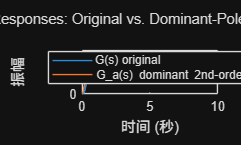

syms s
den = [1 77 2051 21325 80000 406250];
factor(poly2sym(den, s));

sysga = tf(0.512, [1, 2, 26]);
figure; grid on; hold on;
step(sys, sysga, 10);
legend('G(s) original','G_a(s) dominant 2nd-order','Location','best');
title('Step Responses: Original vs. Dominant-Pole Approximation');

% HW5
num = [8000];
den = [1, 637, 7571, 44685, 194400, 406250];
sys = tf(num,den);
p5 = pole(sys)

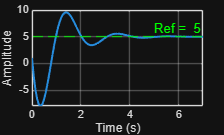

% HW7
clc;clear
a1 = -51;
num = [1, a1, 50];
den = [1, 2, 10];

sys = tf(num, den);
[y, t] = step(sys, 7);
plot(t, y, 'LineWidth', 1.5);
yline(5, '--g', 'Ref =  5')
xlim([0, 7]);
ylim([-8,10]);
grid on;
xlabel('Time (s)'); ylabel('Amplitude');